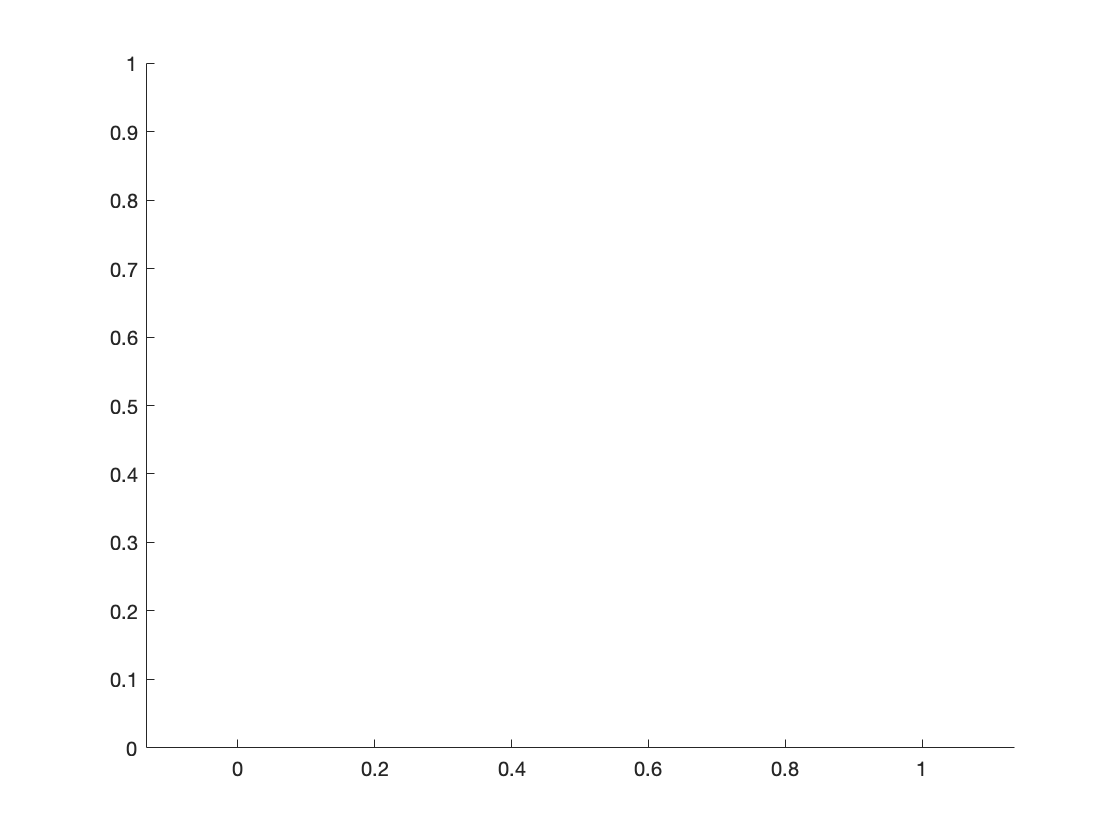

ans = logical
   1


load testcase_01.mat;

% c = '303431432';
d = 1;
clf;
ax = axes;
hold(ax,'on');
axis(ax,'equal')
min_x = a_i(1,1);
max_x = a_i(1,1);
min_y = a_i(2,1);
max_y = a_i(2,1);
direction = 1;
dis_x = 1;
dis_y = 1;
p = [1.5;sqrt(3)/2]*d*(a_i(1,1)-1)+[-1.5;sqrt(3)/2]*d*(a_i(2,1)-1)+[0;sqrt(3)];
%     _ 1
% 6 /   \2
% 5 \ _ /3
%     4
current_position = a_i;
pre_position = [0;0];
length(c);
pair = a_i;
for i = 1:length(c)
    pre_position = current_position;
    if (c(i) == '1')
        current_position(1,1) = current_position(1,1)+dis_x;
        current_position(2,1) = current_position(2,1)+dis_y;
        find_x = find(O(1,:)==current_position(1,1));
        find_y = find(O(2,:)==current_position(2,1));
        if isempty((intersect(find_y,find_x)))
            pair = [pair current_position];
            p = [p [1.5;sqrt(3)/2]*d*(current_position(1,1)-1)+[-1.5;sqrt(3)/2]*d*(current_position(2,1)-1)+[0;sqrt(3)]];
        else
            current_position = pre_position;
        end
    elseif (c(i) == '2')
            current_position(1,1) = current_position(1,1)-dis_x;
            current_position(2,1) = current_position(2,1)-dis_y;
        find_x = find(O(1,:)==current_position(1,1));
        find_y = find(O(2,:)==current_position(2,1));
        if isempty((intersect(find_y,find_x)))
            pair = [pair current_position];
            p = [p [1.5;sqrt(3)/2]*d*(current_position(1,1)-1)+[-1.5;sqrt(3)/2]*d*(current_position(2,1)-1)+[0;sqrt(3)]];
        else
            current_position = pre_position;
        end
    elseif (c(i) == '4')
        direction = direction +1;
        if(direction == 7)
            direction = 1;
        end
    elseif (c(i) == '3')
        direction = direction - 1;
        if(direction == 0)
            direction = 6;
        end
    end
    if (direction == 1)
        dis_x = 1;
        dis_y = 1;
    elseif (direction == 2)
        dis_x = 1;
        dis_y = 0;
    elseif (direction == 3)
        dis_x = 0;
        dis_y = -1;
    elseif (direction == 4)
        dis_x = -1;
        dis_y = -1;
    elseif (direction == 5)
        dis_x = -1;
        dis_y = 0;
    elseif (direction == 6)
        dis_x = 0;
        dis_y = 1;
    end
end

isequal(p,P)
min([pair(1,:) O(1,:)])
max(pair(1,:))
min(pair(2,:))
max(pair(2,:))

